**Load golf ball data**

close all;
clear;

% Load golf shot data
filename = '7_iron_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

% figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 8192; %FFT length
L = 1432; %Window length
overlap = floor(0.88*L); % 50% overlap
N = -0.5; % User-defined. Used for adaptive threshold later.

% Interpolate time data: zero padding is fine


**Using wvtool to select window:**

%Testing window functions
w1 = kaiser(L,6.5);
w2 = window(@blackman,L); 
w3 = window(@gausswin,L); 
% wvtool(w1,w2,w3)
W = w1.'; % Chosen window (as a row vector)

**Signal data:**

% SIGNAL
signal = GolfBallData;
% signal = signal(floor(0.3*fs):floor(6.2*fs));

**Applying a HPF:**

% Load HPF
load('HPF_1.5kHz.mat')

% HPF: pass = 1500Hz, stop = 1300Hz
% Filter designed using filter designer app in MATLAB
A = floor(length(Num)/2);
signal = conv(signal,Num);
signal = signal(A:end-A);

**Calling Spectrogram function:**

%Spectrogram 
[Spec,freq,Spec_t,Spec_mag] = spectrogram(signal,w1,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames
Spec_mag = 10*log10(Spec_mag);



**Adaptive threshold using modal intensity + N*(std. dev.):**

hist_length = floor(f_bins/8); % Length hist = 1/8 of num. frames
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:f_bins
       if frame(j) < threshold %If element in frame is less than threshold then set to -100 dB
           frame(j) = 0;
       end
    end
   
    Spec_mag(:,i) = frame;
end

**Plotting Spectrogram:**

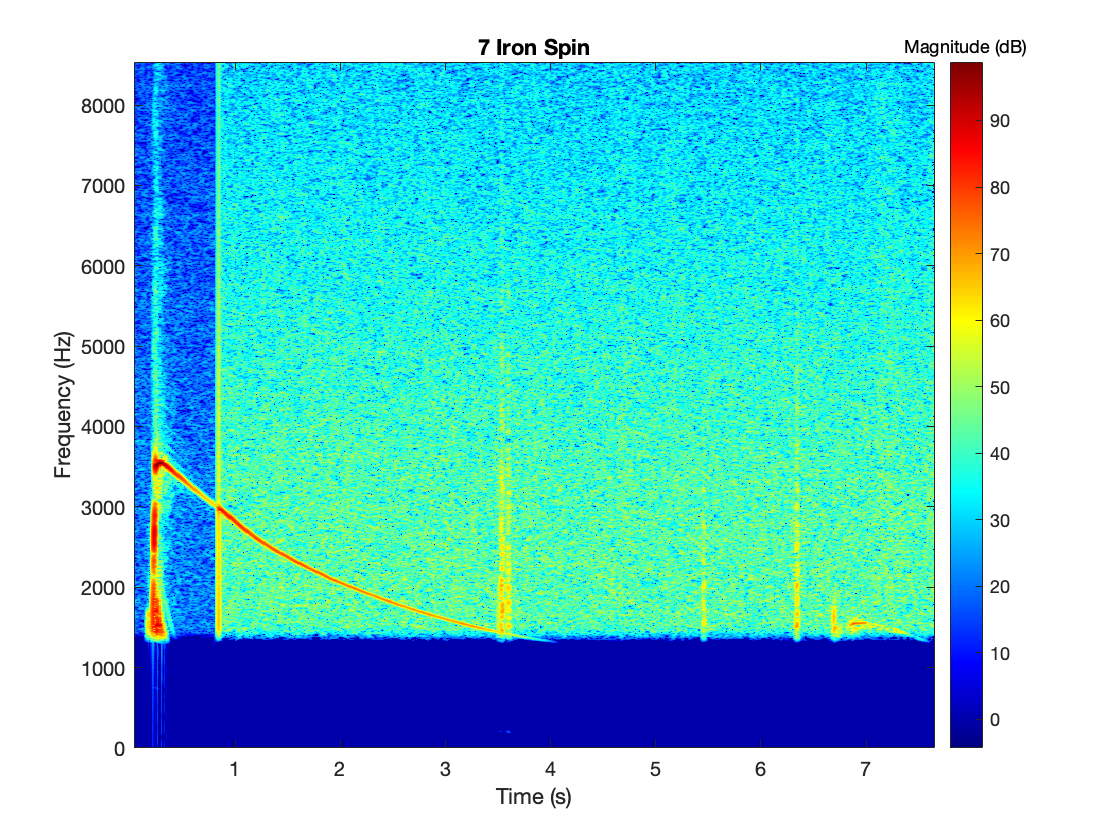

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("7 Iron Spin"), xlabel("Time (s)"),ylabel("Frequency (Hz)")

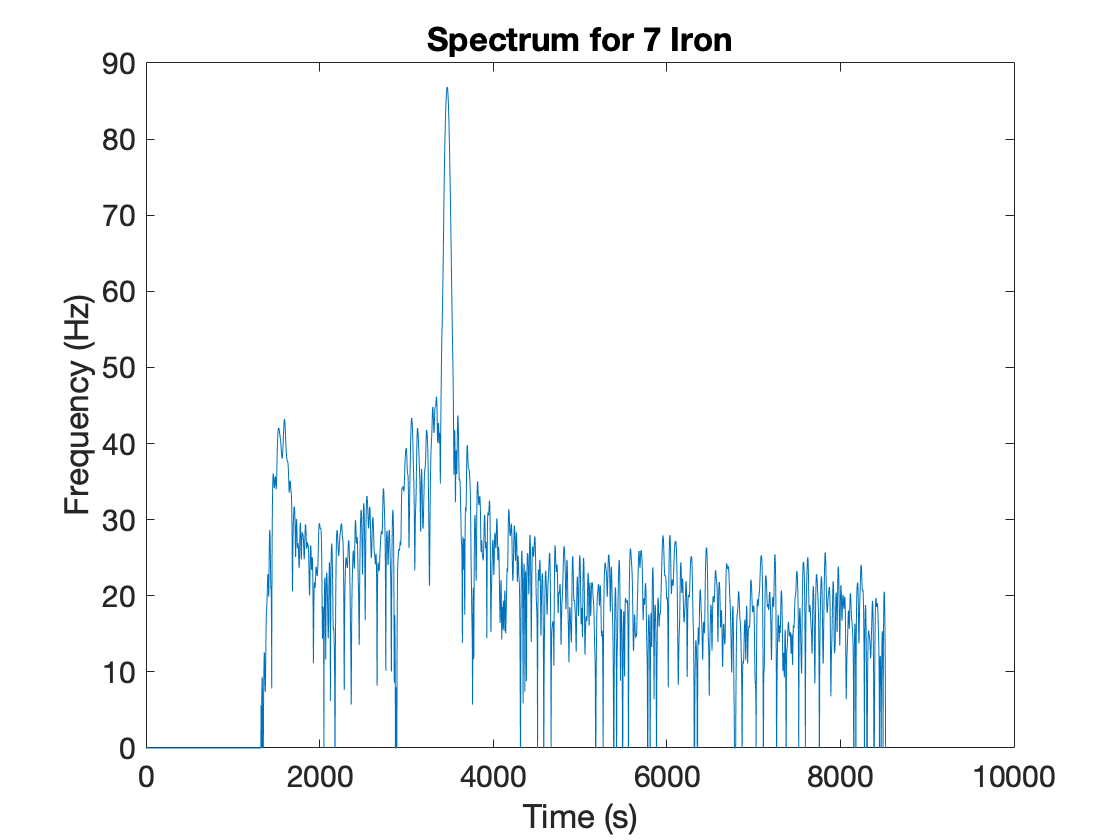

plot(freq,Spec_mag(:,35));
title("Spectrum for 7 Iron",'FontSize',16), xlabel("Time (s)",'FontSize',16),ylabel("Frequency (Hz)",'FontSize',16);
set(gca,'FontSize',15);